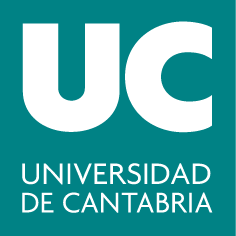

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# ** Guion MATLAB: Funciones**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Conocer la utilidad de programar funciones

- Aprender a definir y utilizar funciones en MATLAB

- Aprender las distintas formas en las que podemos implementar funciones en MATLAB

## **¿Qué es una función y por qué son útiles en programación?**

En la mayoría de los lenguajes de programación, incluido MATLAB, una función es un bloque de código diseñado para realizar una tarea específica. Puede ser vista como una "caja negra" que recibe entradas (argumentos de entrada), realiza operaciones o procesos con esas entradas, y luego produce salidas (argumentos de salida). De esta manera, cuando utilizamos una función programada por otra persona, o disponible en MATLAB, solo necesitamos saber que para qué sirve la función y qué argumentos de entrada y salida tiene, no necesitamos conocer cómo lo hace.

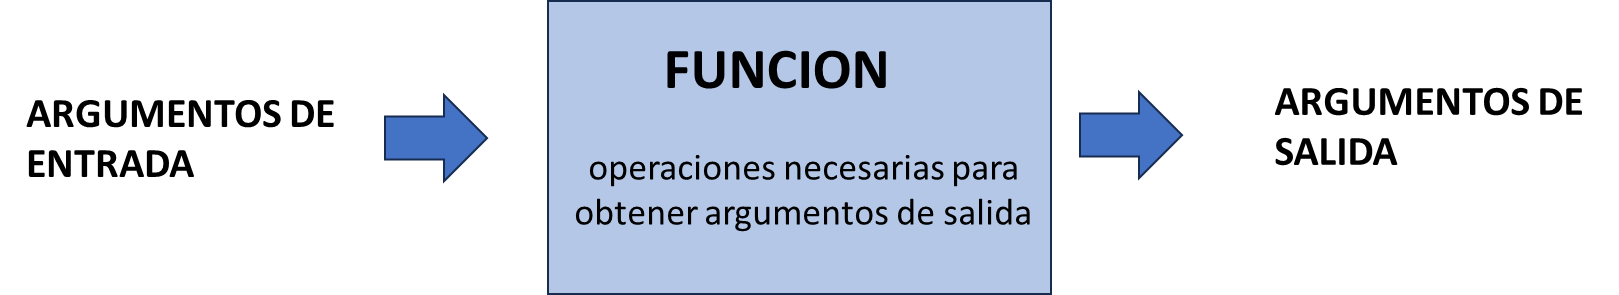

**Importancia de las Funciones**

Las funciones son esenciales por varias razones:

- Modularidad: Permiten dividir tareas complejas en subprocesos más simples y manejables.

- Reutilización: Una vez que creas una función para realizar una tarea específica, puedes reutilizarla en diferentes partes de tu programa o en diferentes programas.

- Organización: Las funciones ayudan a organizar y estructurar tu código de manera más clara, facilitando su lectura y mantenimiento.

**Ejemplos de Funciones**

Una función en programación puede ser tan simple como una función matemática, por ejemplo, $f\left(x\right)=x^2$, que toma un número como argumento de entrada y devuelve su cuadrado como argumento de salida. Sin embargo, en programación, las funciones abarcan una gama mucho más amplia de operaciones. Por ejemplo, una función puede tomar como entrada un número de DNI (sin letra) y devolver como salida la letra correspondiente al DNI.

## **¿Cómo utilizar (llamar) a una función?**

Aunque tal vez nunca hayas definido una función, seguro que ya hayas utilizado alguna. MATLAB ofrece una amplia gama de funciones predefinidas, muchas de las cuales son extremadamente útiles en el campo del álgebra lineal, como la función `det` (para calcular determinantes), `rank` (para determinar el rango de una matriz) o `diag` (para extraer o crear matrices diagonales).

#### Ejemplo función max. 

Por ejemplo, vamos a utilizar la función de MATLAB `max`(). Para ver cómo usar una función siempre es recomendable ver su ayuda

help max

Las funciones de MATLAB suelen ofrecer varias posibilidades de uso, vamos a quedarnos con la primera, que suele ser la más sencilla y  habitual. Si consultas la documentation verás que podemos llamar a la función `max` de la siguiente manera:

 M=max(A)

- Si `A` es un vector, `max(A)` devuelve el máximo de `A`.

v= [1 3 11 22];
max(v)

- si A es una matriz, `max(A)` devolverá un vector fila que contiene el valor máximo de cada columna de `A`.

A= [11 3; 2 22; -2 5 ]
max(A)

Otra de las posibles maneras de llamar a la función `max` es la siguiente `[M,I]=max(A)`. Este caso nos sirve para ilustrar cómo llamar a una función con múltiples argumentos de salida, deberemos hacerlo entre corchetes [], y cada argumento de salida separado por una coma. En este ejemplo además del valor máximo la función devuelve también la posición del vector correspondiente a la primera aparición del valor máximo de `A`. 

Para el vector [1 3 11 22], el máximo es 22 y su posición es la cuarta

[vmax,ind]=max(v)

Es habitual que MATLAB tenga distintas formas de llamar a una función, generalmente las funciones que nosotros definamos tendrán una única sintaxis de llamada. Veamos cómo definir funciones en MATLAB

## **¿Cómo definir una función en MATLAB?**

La estructura básica para definir una función en MATLAB es la siguiente:

`function [outputArg1,outputArg2] = nombredelaFuncion(inputArg1,inputArg2)`

`    % Código que procesa los argumentos de entrada para producir las salidas.`

`end`

MATLAB permite la definición de funciones de tres maneras principales:

- **Archivo de función individual**: Esta es la forma más común de definir funciones en MATLAB. Creas un archivo `.m` cuyo nombre es el mismo que el de la función que contiene. Este método facilita la reutilización y organización de tu código, ya que la función puede ser llamada desde cualquier script o función. Para poder utilizar la función definida en un archivo .m es importante que esté en el mismo directorio o que su ruta esté añadida al path para que MATLAB sea capaz de encontrarla. Cuando llamas a una función MATLAB no busca un archivo con dicho nombre en todo tu ordenador, sino solo en algunas rutas que tiene definidas en el path. Una de ellas es el directorio actual o current folder (la ruta que aparece en la parte superior de MATLAB). Es buena idea guardar tus funciones en el current folder para asegurarte que podrás usarla sin problemas.

- **Funciones locales dentro de scripts**: Puedes definir funciones dentro de un script (o live script) de MATLAB. Estas funciones son accesibles solo dentro del script y son útiles si solo vas a utilizar dicha función dentro del script. Al final de este live script tienes dos ejemplo de funciones: letraDNI y esSimetrica. Para versiones de MATLAB anteriores a 2024a las funciones de locales deben definirse siempre al final de los scripts o live scripts

- **Funciones anónimas**: MATLAB permite la creación de funciones anónimas, las cuales son expresiones que permiten definir funciones simples en una sola línea de código sin necesidad de crear un archivo separado. Las funciones anónimas son útiles para funciones sencillas que pueden escribirse en una única línea de código. A continuación tienes un ejemplo, 

% Ejemplo de función anónima
cuadrado = @(x) x^2;
% Uso de la función anónima
resultado = cuadrado(4); 


## Gestión de memoria y ámbito de variables en funciones

En MATLAB, como en muchos otros lenguajes de programación, las variables definidas dentro de una función tienen un ámbito local. Esto implica que estas variables solo existen y pueden ser utilizadas dentro de la función donde fueron definidas. Es decir, si defines una variable dentro de una función, esta variable no será accesible en la línea de comandos de MATLAB. 

## Ejemplos de funciones

### Función para predecir letra DNI. 

La función letraDNI  predice la letra del número de identidad. 

- argumento de entrada: número de identidad

- argumento de salida: letra del DNI

La implementación de la función se encuentra al final de este live script.

Ejemplo de uso de la función letraDNI

dni=20265066
letra = letraDNI(dni)

 La letra del DNI se calcula a partir del número del DNI, dividiéndolo por 23 y tomando el resto de esta división, que luego se usa para seleccionar una letra de un conjunto predeterminado de 23 letras. Para calcular el resto (módulo) de una división utilizaremos la función `mod`().

#### **Ejercicio**. 

Llama a continuación a la función letraDNI y comprueba si predice tu letra del DNI correctamente.

### Función para determinar si una matriz es simétrica o antisimeétrica

La función verificarSimetria comprueba si una matriz A  es simétrica o antisimétrica. Devuelve dos argumentos de salida, esSimetrica y esAntisimetrica que respectivamente indican si la matriz A es simétrica (esSimetrica=1) o antisimétrica (esAntisimetrica=1). La implementación de la función se encuentra al final de este live script.

#### **Ejercicio**. 

Define una matriz simétrica, y otra antisimétrica y utiliza la función verificarSimetria para comprobar su simetría.

### Código de las funciones locales letraDNI y verificarSimetria

A continuación se muestra el código de ambas funciones ejemplo. Estas funciones locales al estar dentro de un script o live script siempre deben ir definidas al final.

Definición de la función `letraDNI`:

function letra = letraDNI(numeroDNI)
    % Calcula la letra del DNI español
    % Argumento de entrada: numeroDNI (número sin la letra)
    % Argumento de salida: letra (la letra del DNI)

    % letras según el orden establecido para la determinación de la letra del DNI
    letras = 'TRWAGMYFPDXBNJZSQVHLCKE';

    % Calcula el índice de la letra correspondiente
    indice = mod(numeroDNI, 23) + 1;  % sumamos 1 porque MATLAB indexa desde 1

    % Selecciona la letra correspondiente
    letra = letras(indice);
end


Definición de la funcion `verificarSimetria`

function [esSimetrica, esAntisimetrica] = verificarSimetria(matriz)
    % Verifica si la matriz es simétrica y/o antisimétrica de manera simplificada.
    % Argumentos de entrada:
    % - A: Una matriz cuadrada.
    % Argumentos de salida:
    % - esSimetrica: Verdadero (1) si la matriz es simétrica, Falso (0) sino lo es.
    % - esAntisimetrica: Verdadero (1) si la matriz es antisimétrica, Falso (0) sino lo es.
    
    % Comprobar simetría
    esSimetrica = isequal(matriz, matriz');
    
    % Comprobar antisimetría
    esAntisimetrica = isequal(matriz, -matriz');
end

#### **Nota  sobre los errores de redondeo y el uso de **`isequal`** en comparaciones**

En este ejemplo, utilizamos la función `isequal` para verificar si una matriz es simétrica o antisimétrica comparándola directamente con su transpuesta (y su transpuesta negativa para la antisimetría). Esto es conceptualmente sencillo y directo.

Sin embargo, es importante ser consciente de que el uso de `isequal` para comparar matrices (o cualquier tipo de datos numéricos) que han resultado de cálculos previos puede no ser apropiado en todas las situaciones. Esto se debe a que los cálculos realizados en el ordenador pueden introducir pequeños errores de precisión o redondeo, los cuales son normales y esperados debido a la representación finita de los números en las computadoras. Recuerda, ¡tu ordenador no puede guardar los infinitos decimales del número $\pi$! En tales casos, dos valores que teóricamente deberían ser iguales (como el resultado de una operación matemática y su valor teórico exacto) pueden no serlo estrictamente debido a estos pequeños errores. Por lo tanto, cuando se trabaja con resultados de cálculos numéricos, como muchos de los métodos del álgebra lineal es recomendable utilizar métodos de comparación que incluyan una cierta tolerancia para estos pequeños errores. 